# 2.4 Péndulo invertido linealizado

Partimos de las ecuaciones


$$\dot x_1 = x_2 \\ 
\dot x_2 = \frac{g}{l} \sin x_1 - \frac{b}{ml} x_2$$


donde $x_1 =\theta$ y $x_2 =\dot{\;\theta }$. 

**a)**

El sistema se puede linealizar alrededor del punto de equilibrio $\left(0,\pi \right)\ldotp$ Para ello hago uso del teorema de Taylor.

syms x1 x2 g l b m
s(1, 1) = x2;
s(2, 1) = g*l*sin(x1) - b/(m*l)*x2;
slin = subs(jacobian(s, [x1, x2]), {x1, x2}, {pi, 0}) * [x1 - pi; x2]

$$slin = \left(\begin{array}{c} x_{2}\\ -g\,l\,\left(x_{1}-\pi \right)-\frac{b\,x_{2}}{l\,m} \end{array}\right)$$

**b)**

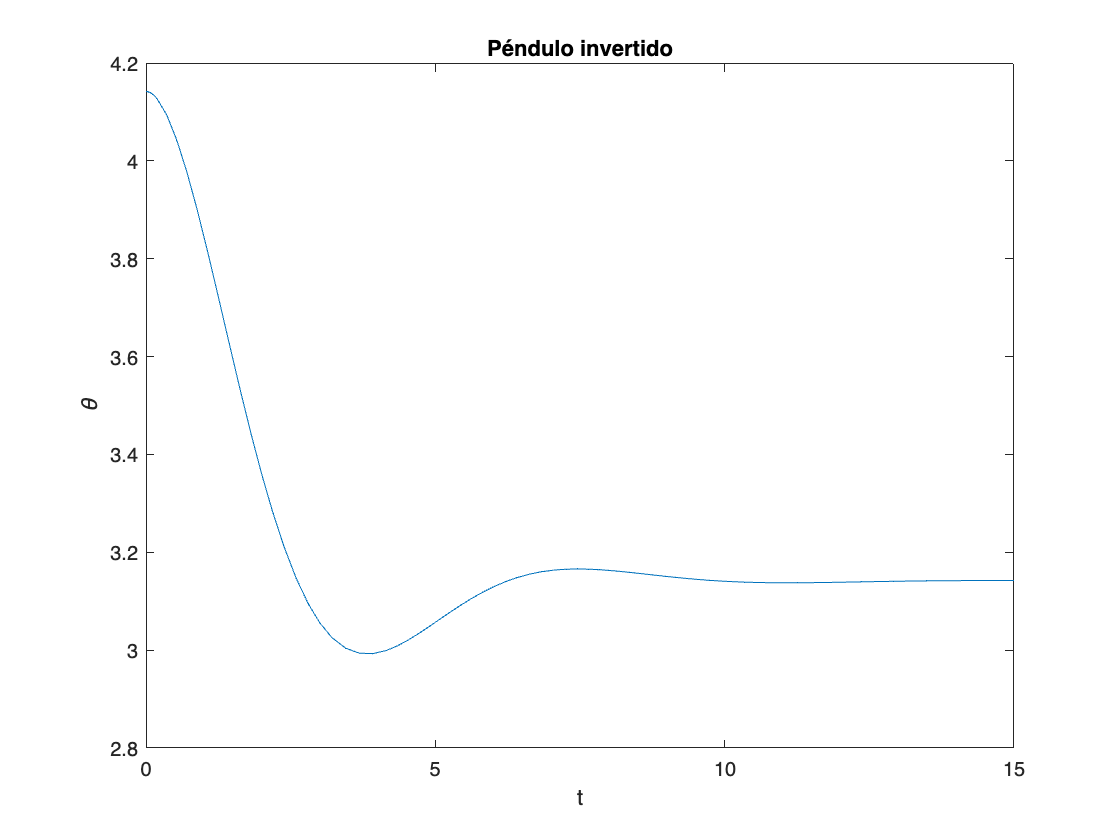

clear; close all; clc; clf;

[m, g, l, b] = deal(1);

tspan = [0, 15];

x0 = [pi; 0];
dx0 = [1; 0]; %Perturbación de la situación inicial

%Simulación del sistema original

[t, x] = ode45(@(t, x)invpendulum(t, x, m, g, l, b), tspan, x0 + dx0);

plot(t, x(:, 1));

xlabel("t");
ylabel("\theta");
title("Péndulo invertido");

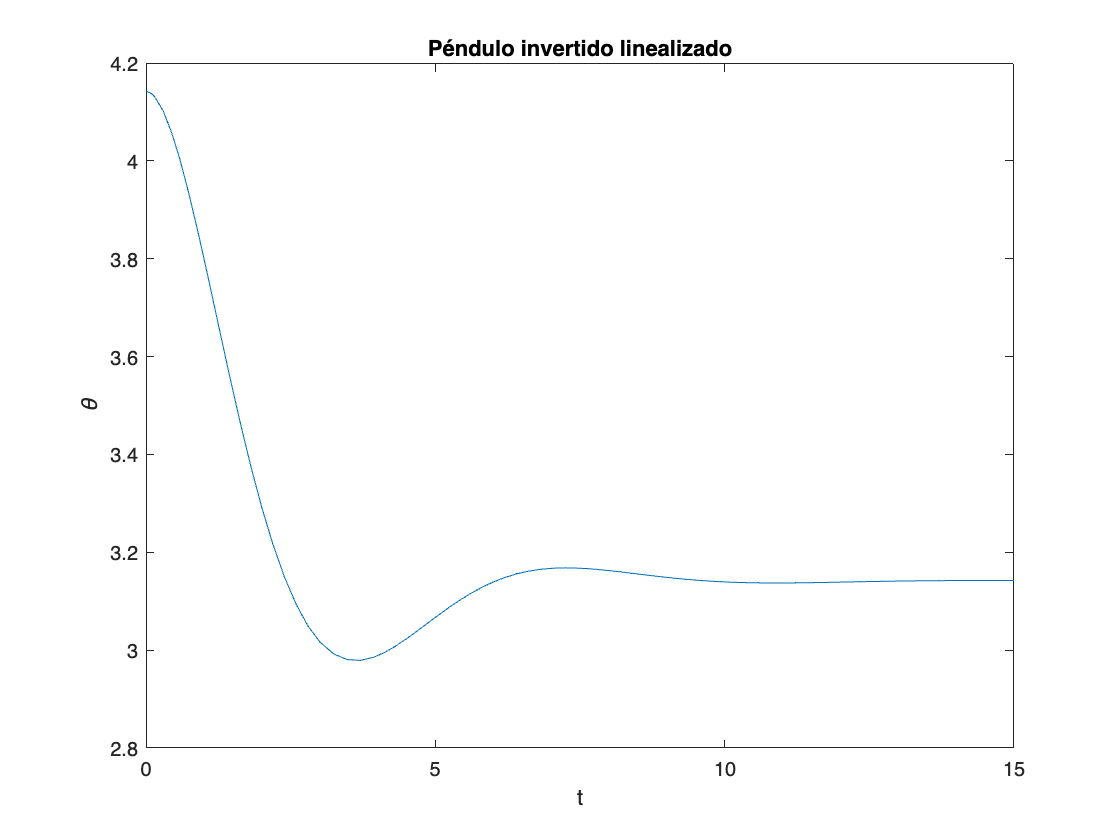

%Linealización

[t, x] = ode45(@(t, dx)linvpendulum(t, dx, m, g, l, b), tspan, x0 + dx0);

plot(t, x(:, 1));
xlabel("t");
ylabel("\theta");
title("Péndulo invertido linealizado");

Lo voy a hacer para estados iniciales en el punto de equilibrio con perturbaciones de posición cada vez más grandes. 

tt = "Perturbación de 5.000000e-01 radianes"

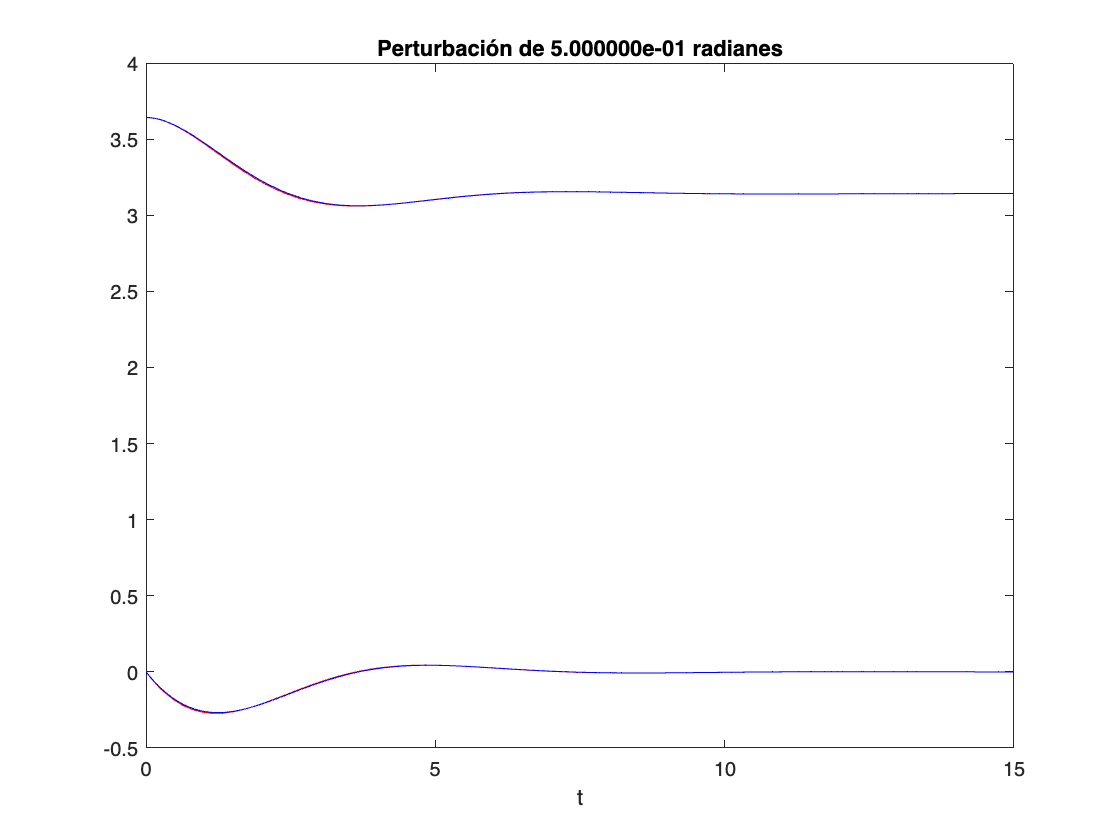

tt = "Perturbación de 1 radianes"

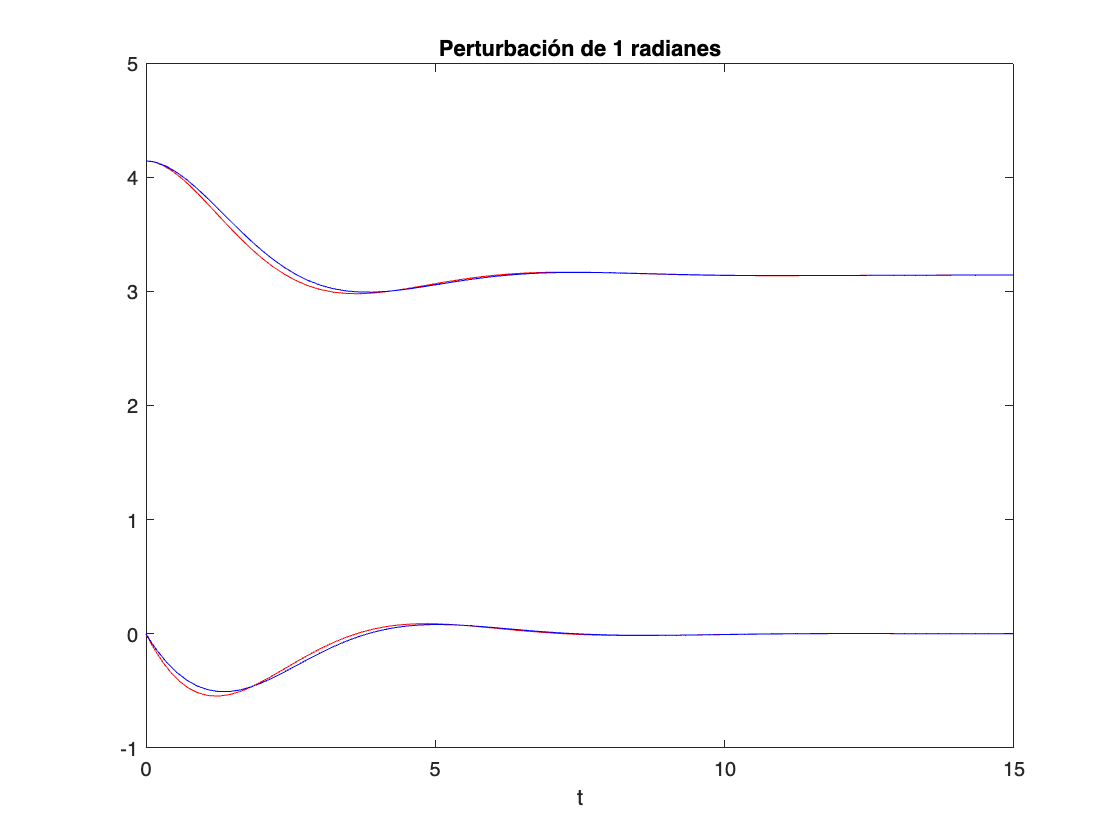

tt = "Perturbación de 1.500000e+00 radianes"

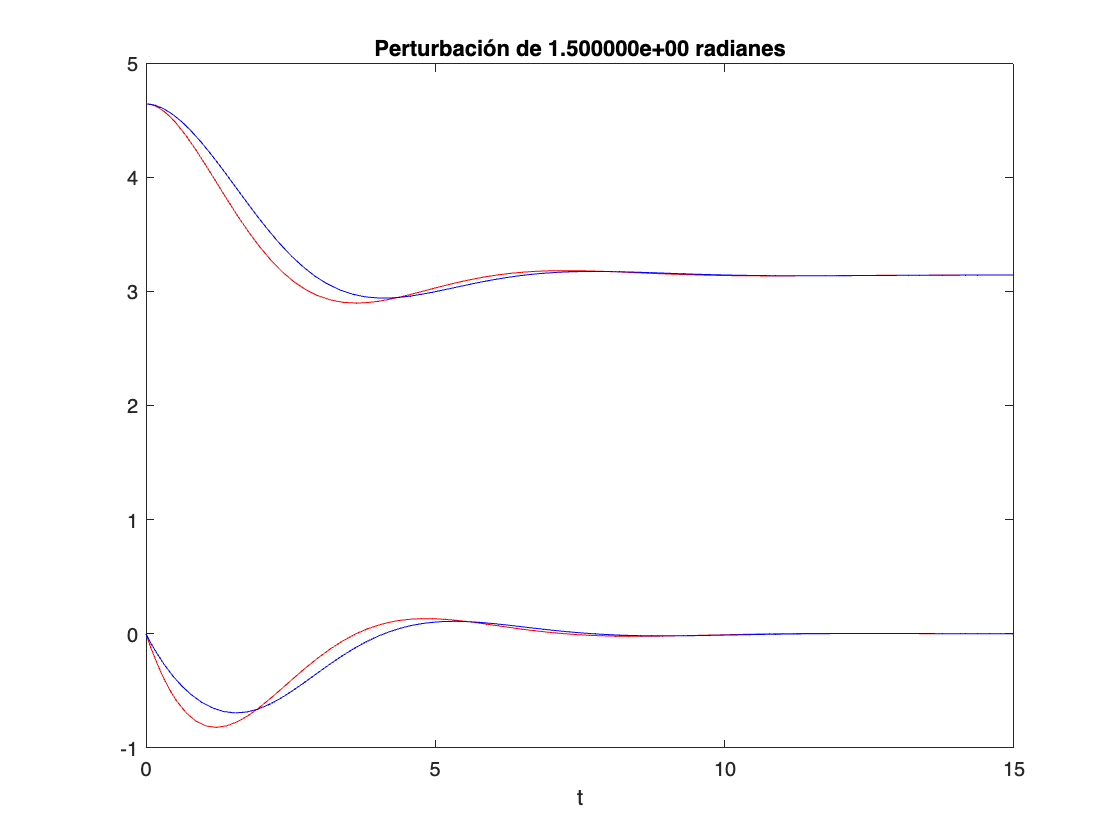

tt = "Perturbación de 2 radianes"

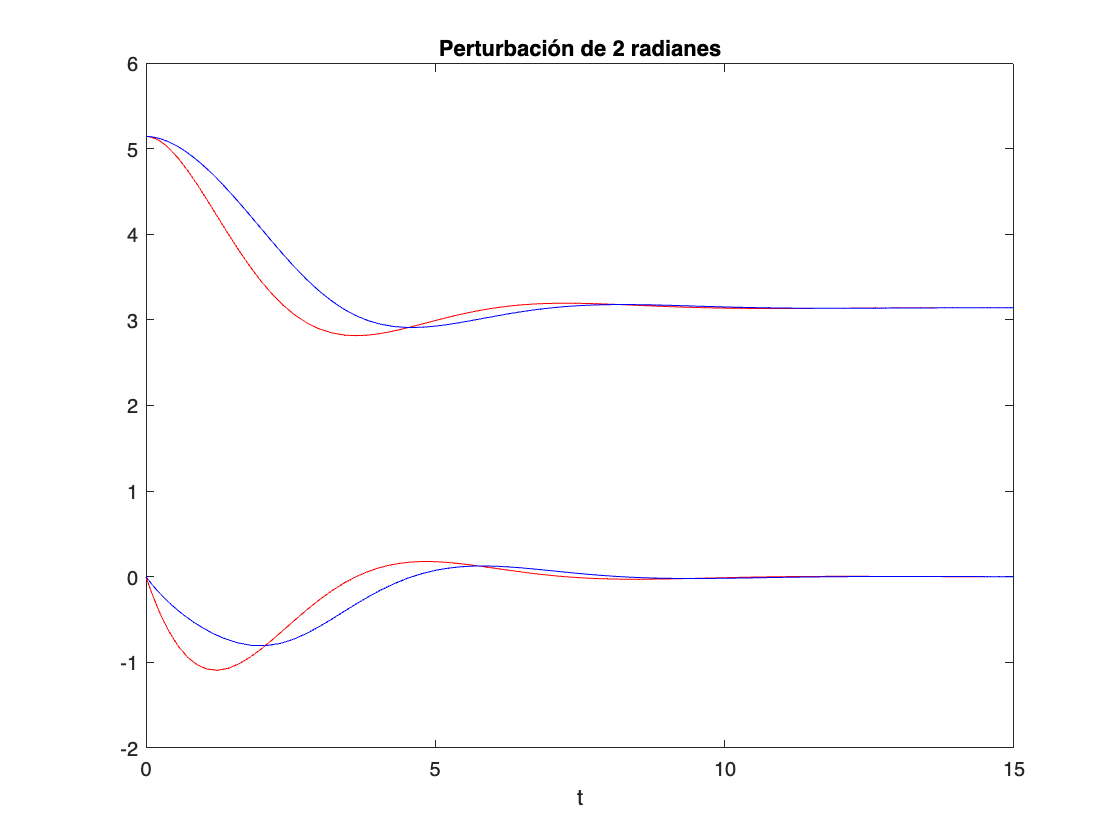

tt = "Perturbación de 2.500000e+00 radianes"

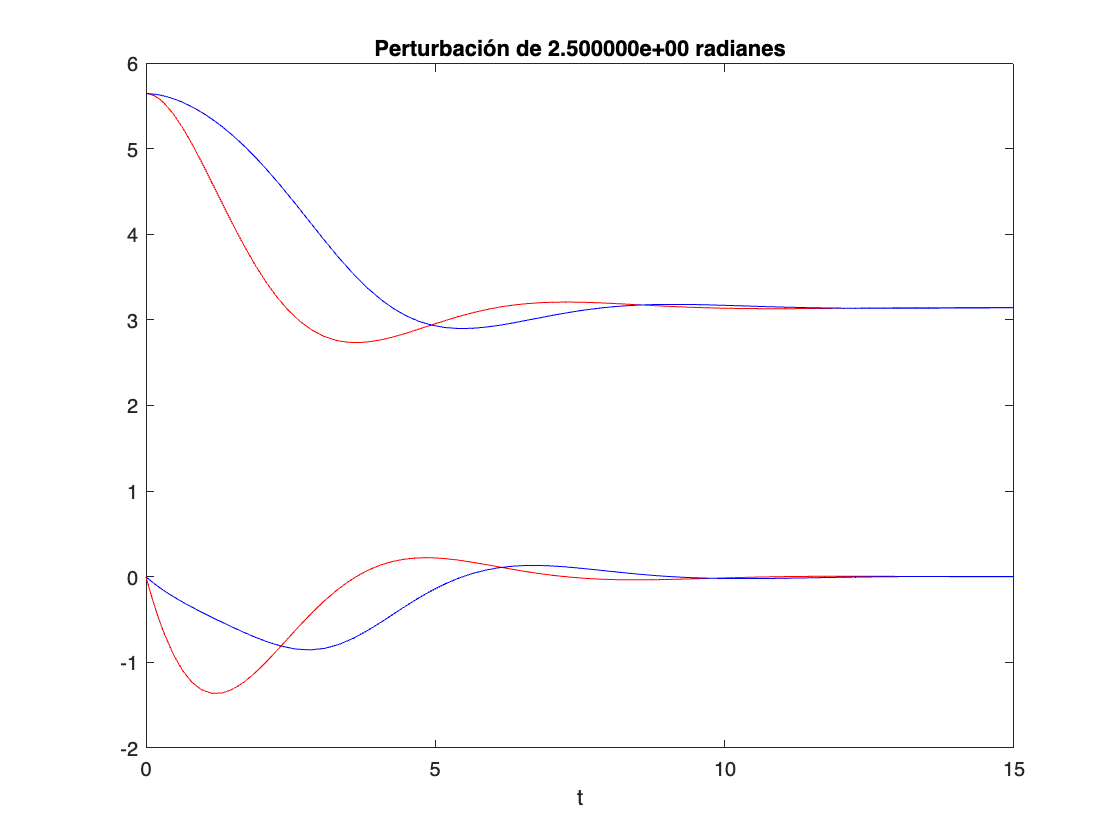

tt = "Perturbación de 3 radianes"

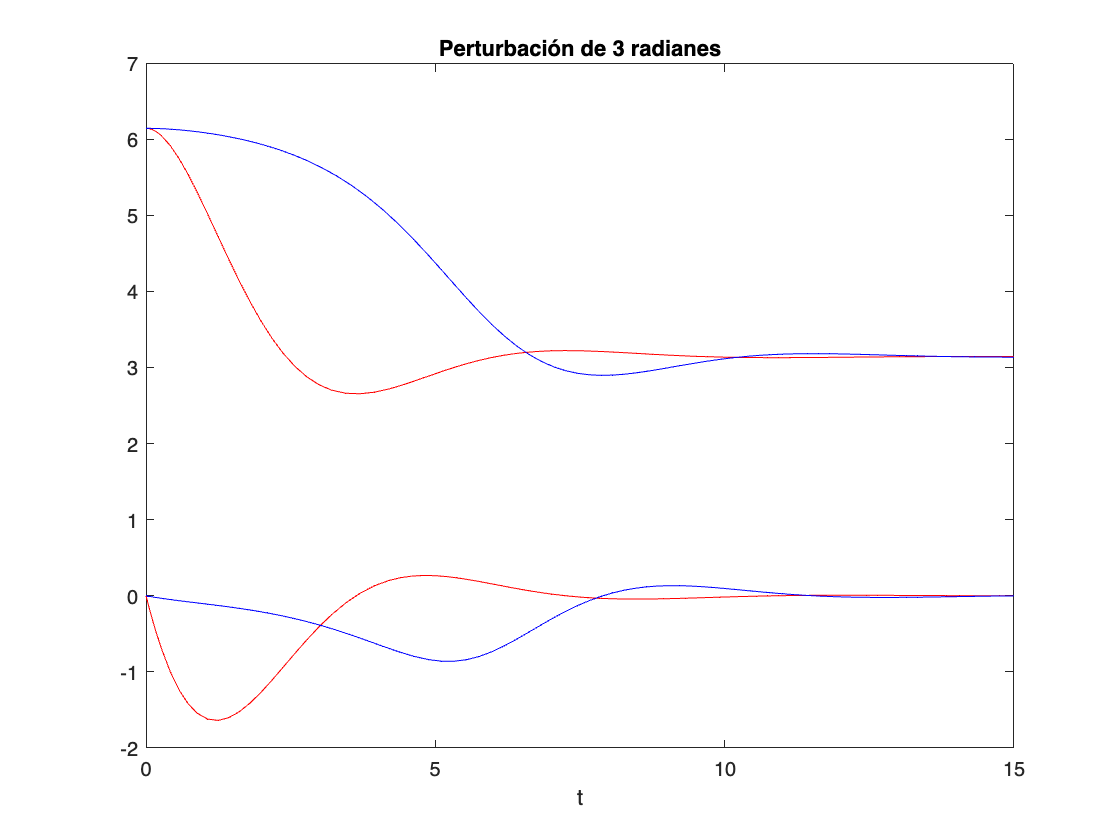

tt = "Perturbación de 3.500000e+00 radianes"

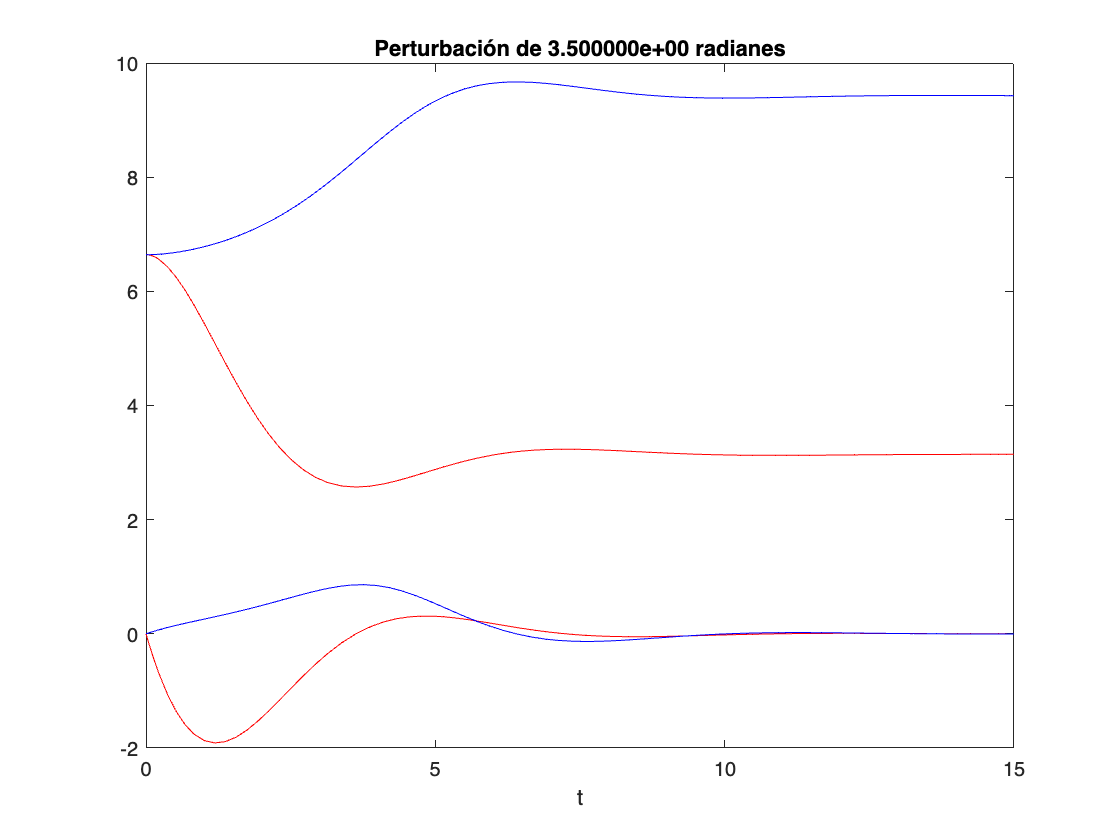

tt = "Perturbación de 4 radianes"

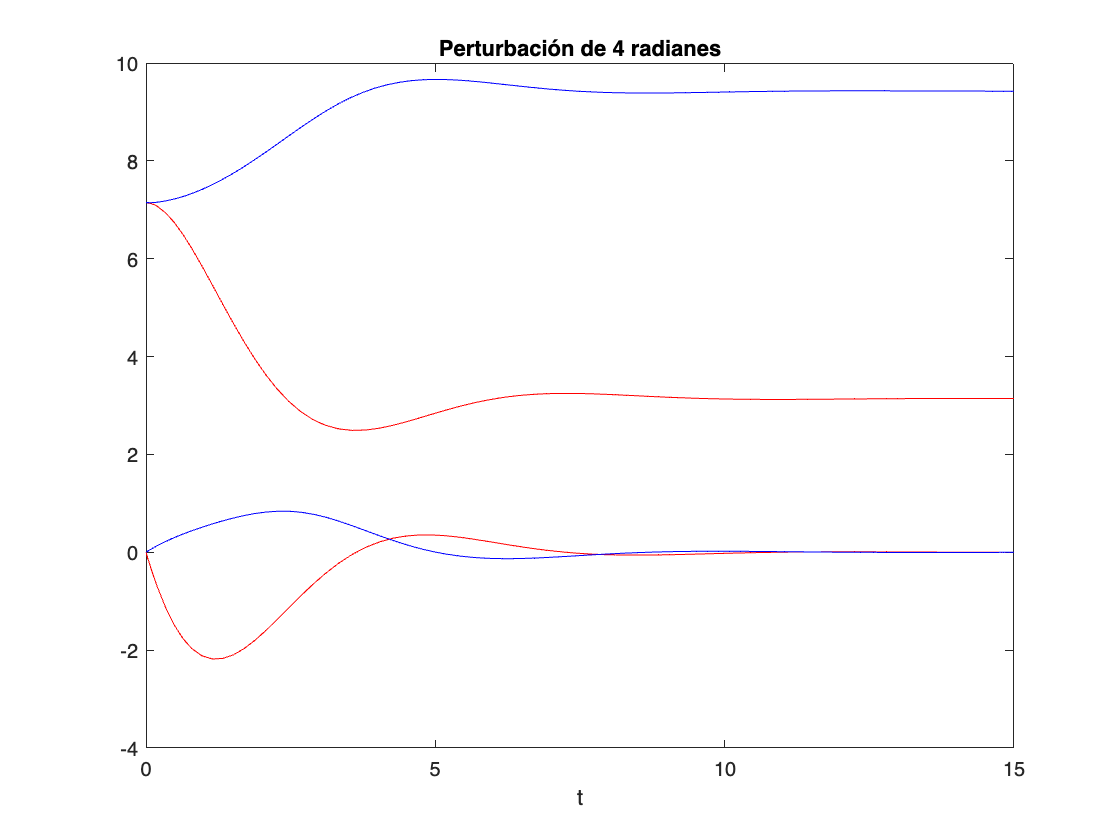

format short 
for i = 0.5:0.5:4
    figure;
    dx0 = i.*[1; 0];
    tt = sprintf("Perturbación de %d radianes", i);
    [t, x] = ode45(@(t, dx)linvpendulum(t, dx, m, g, l, b), tspan, x0 + dx0);
    plot(t, x(:, 1), "r"); hold on;
    plot(t, x(:, 2), "r");
    [t, x] = ode45(@(t, x)invpendulum(t, x, m, g, l, b), tspan, x0 + dx0);
    plot(t, x(:, 1), "b");
    plot(t, x(:, 2), "b");
    xlabel("t");
    title(tt);
    hold off;
end

Se aprecia claramente cómo para perturbaciones pequeñas ambas soluciones, linealizada (roja) y original (azul), son se solapan, siendo válidas, pero a medida que la perturbación aumenta, estas se vuelven también cada vez más dispares. Llega un punto (concretamente, una vez la perturbación supera la media vuelta o $\pi$ radianes) en el que el sistema original tiende a otro punto de equilibrio equivalente ($3\pi ,0$) (es decir, se cae por el otro lado), pero el linealizado fuerza siempre la vuelta al punto sobre el cual se ha construido, ($\pi ,0$). Por tanto, está claro que las soluciones para el lineal dejan de ser válidas. 

function xdot = invpendulum(t, x, m, g, l, b)
    xdot(1, 1) = x(2, 1);
    xdot(2, 1) = g/l * sin(x(1, 1)) - b/(m * l) * x(2, 1);
end


%Linealizado en torno a (pi, 0)
function dxlin = linvpendulum(t, dx, m, g, l, b)
    dxlin(1, 1) = dx(2, 1); %Esta nos queda igual que en la original
    dxlin(2, 1) = - g * l * (dx(1, 1) - pi) - b / (m * l) * dx(2, 1);
end